clear
clc
close all

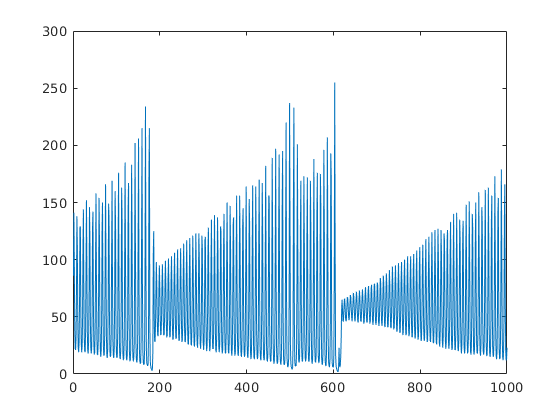

% Reading in and plotting training data
data_train = readtable("lasertrain.dat");
data_train(:,1:3) = [];
data_train = table2array(data_train)';

figure
plot(data_train)

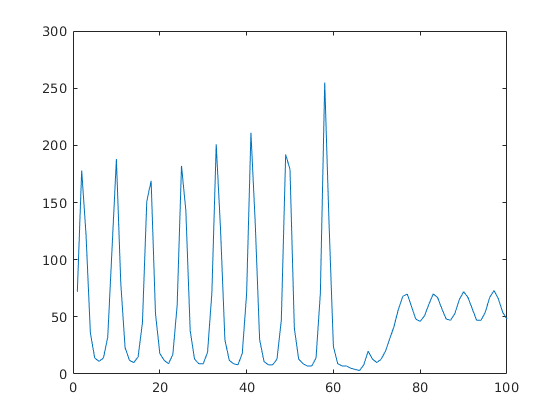

% Reading in and plotting test data
data_test = readtable("laserpred.dat");
data_test(:,1:3) = [];
data_test = table2array(data_test)';

figure
plot(data_test)


data = cat(2, data_train, data_test);

## Standardize Data

For a better fit and to prevent the training from diverging, standardize the training data to have zero mean and unit variance. At prediction time, you must standardize the test data using the same parameters as the training data.

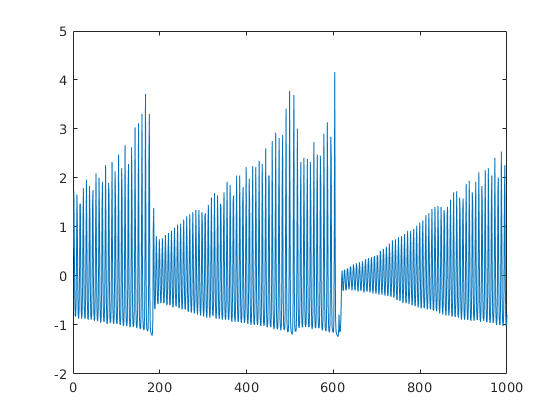

mu = mean(data_train);
sig = std(data_train);

data_train_standardised = (data_train - mu) / sig;
plot(data_train_standardised)

lag = 20;
numTimeStepsTrain = length(data_train) - lag;
[XTrain_temp, YTrain_temp] = getTimeSeriesTrainData(data_train_standardised', lag)

XTrain_temp =     0.5569    1.7302    0.7489   -0.4031   -0.8084   -0.8297   -0.5951    0.2583    1.6662    1.0903   -0.2537   -0.7871   -0.8724   -0.7017   -0.0191    1.4742    1.4742   -0.0404   -0.7017   -0.8724   -0.7657   -0.2964    1.1116    1.7942    0.2796   -0.6377   -0.8511   -0.8724   -0.4884    0.6849    1.9649    0.7063   -0.5097   -0.8511   -0.8937   -0.6591    0.2369    1.8369    1.2183   -0.2964   -0.7871   -0.8937   -0.8084   -0.1684    1.4529    1.7516    0.0449   -0.7231   -0.9151   -0.8724
    1.7302    0.7489   -0.4031   -0.8084   -0.8297   -0.5951    0.2583    1.6662    1.0903   -0.2537   -0.7871   -0.8724   -0.7017   -0.0191    1.4742    1.4742   -0.0404   -0.7017   -0.8724   -0.7657   -0.2964    1.1116    1.7942    0.2796   -0.6377   -0.8511   -0.8724   -0.4884    0.6849    1.9649    0.7063   -0.5097   -0.8511   -0.8937   -0.6591    0.2369    1.8369    1.2183   -0.2964   -0.7871   -0.8937   -0.8084   -0.1684    1.4529    1.7516    0.0449   -0.7231   -0.9151   -0

YTrain_temp =    -0.7657   -0.2964    1.1116    1.7942    0.2796   -0.6377   -0.8511   -0.8724   -0.4884    0.6849    1.9649    0.7063   -0.5097   -0.8511   -0.8937   -0.6591    0.2369    1.8369    1.2183   -0.2964   -0.7871   -0.8937   -0.8084   -0.1684    1.4529    1.7516    0.0449   -0.7231   -0.9151   -0.8724   -0.4884    0.8556    2.0929    0.5569   -0.5951   -0.9151   -0.9151   -0.7017    0.2583    2.0076    1.2396   -0.3604   -0.8511   -0.9577   -0.8297   -0.2751    1.4529    1.9222    0.0663   -0.7657


XTrain = cell(length(data_train)-lag,1);
for i=1:length(XTrain_temp)
    XTrain{i} = XTrain_temp(:,i)';
end

YTrain = YTrain_temp';

num_features = 1;
num_responses = 1;
num_hidden_units = 200;

layers = [ ...
    sequenceInputLayer(num_features)
    lstmLayer(num_hidden_units,"OutputMode","last")
    fullyConnectedLayer(num_responses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',250, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

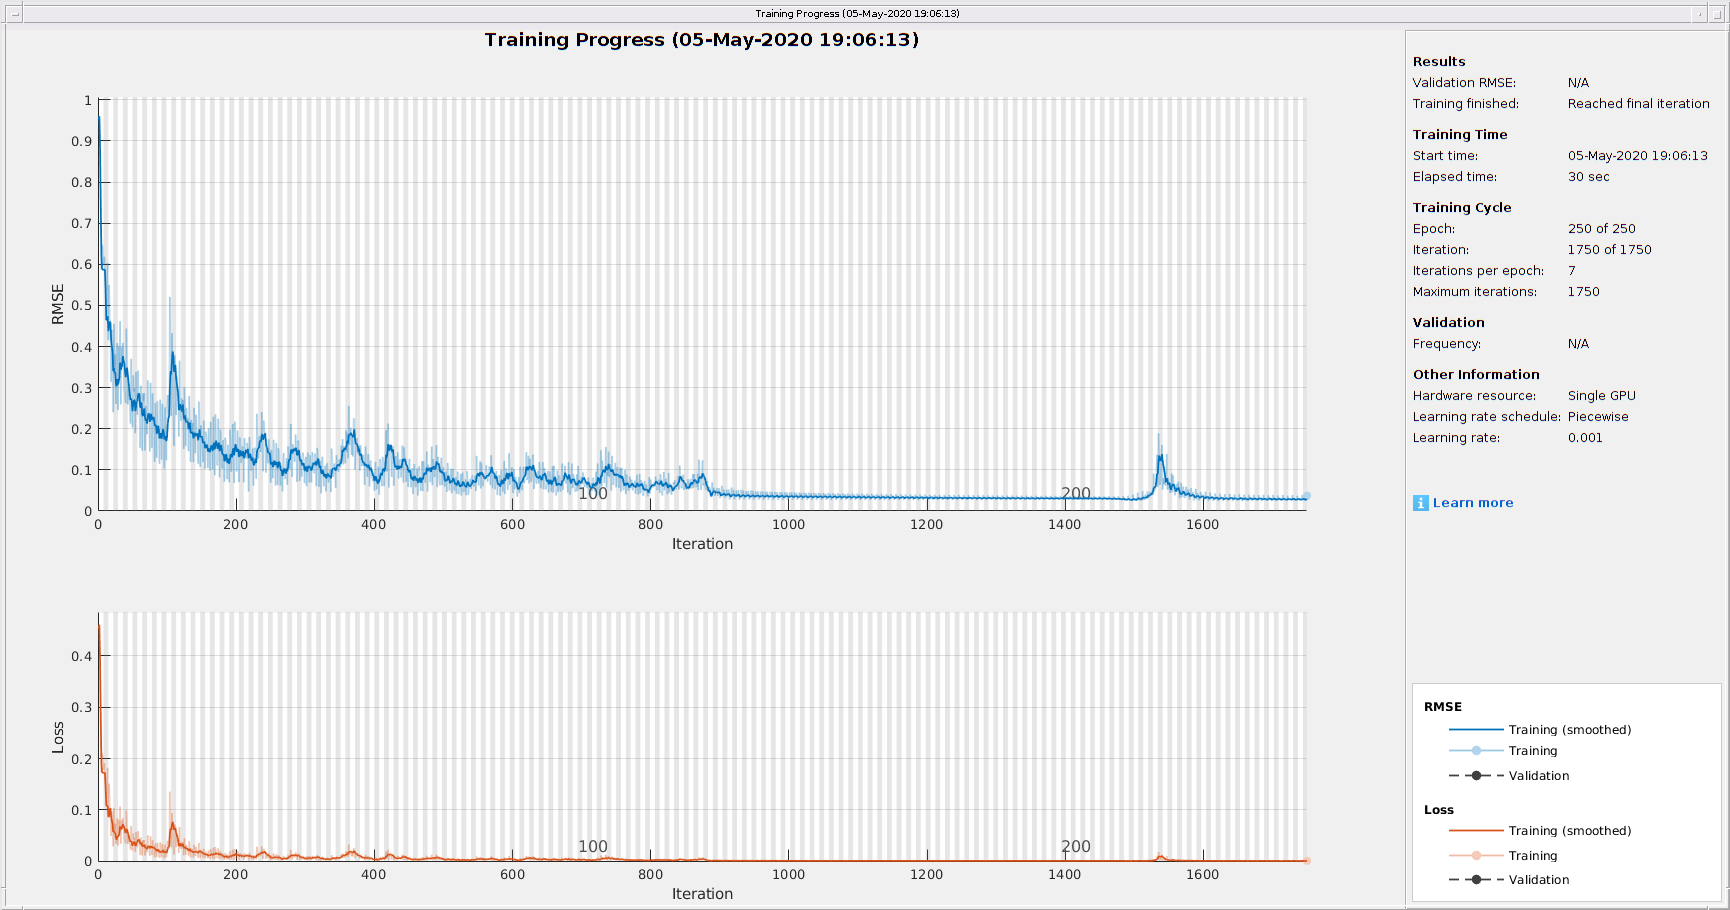

net = trainNetwork(XTrain,YTrain,layers,options);

data_test_standardised = (data_test - mu) / sig;
XTest = data_test_standardised(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end-lag),'MiniBatchSize',27);

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

Reference to a cleared variable YPred.

YPred = sig*YPred + mu;

YTest = data_test(2:end);
rmse = sqrt(mean((YPred-YTest).^2))

figure
plot(data_train(1:end-lag))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[data(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])

figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

## Prepare Predictors and Responses

% Getting target and training data with lag
% lag = 30;
% [x_train_temp, y_train] = getTimeSeriesTrainData(data_train_standardised, lag);
% 
% % Formatting training data for trainNetwork function
% x_train = cell(1000-lag,1);
% 
% for i=1:(1000-lag)
%     x_train{i,1} = x_train_temp(:,i)';
% end
% 
% y_train = y_train';

## **Define LSTM Network Architecture**

Create an LSTM regression network. Specify the LSTM layer to have 200 hidden units.

% num_features = 1;
% num_responses = 1;
% num_hidden_units = 200;
% 
% layers = [ ...
%     sequenceInputLayer(num_features)
%     lstmLayer(num_hidden_units, 'OutputMode','last')
%     fullyConnectedLayer(num_responses)
%     regressionLayer];
% 
% options = trainingOptions('adam', ...
%     'MaxEpochs',300, ...
%     'GradientThreshold',1, ...
%     'InitialLearnRate',0.005, ...
%     'LearnRateSchedule','piecewise', ...
%     'LearnRateDropPeriod',150, ...
%     'LearnRateDropFactor',0.2, ...
%     'Verbose',0, ...
%     'Plots','training-progress');

## Train LSTM Network

Train the LSTM network with the specified training options by using `trainNetwork`.

% net = trainNetwork(x_train,y_train,layers,options);

## Forecast Future Time Steps

To forecast the values of multiple time steps in the future, use the `predictAndUpdateState` function to predict time steps one at a time and update the network state at each prediction. For each prediction, use the previous prediction as input to the function.

Standardize the test data using the same parameters as the training data.

% data_test = readtable("laserpred.dat");
% data_test(:,1:3) = [];
% data_test = table2array(data_test);
% num_timesteps_test = numel(data_test);
% 
% figure
% plot(data_test)

% data_test_standardised = (data_test - mu) / sig;

To initialize the network state, first predict on the training data `XTrain`. Next, make the first prediction using the last time step of the training response `YTrain(end)`. Loop over the remaining predictions and input the previous prediction to `predictAndUpdateState`.

% %net = predictAndUpdateState(net,x_train);

For large collections of data, long sequences, or large networks, predictions on the GPU are usually faster to compute than predictions on the CPU. Otherwise, predictions on the CPU are usually faster to compute. For single time step predictions, use the CPU. To use the CPU for prediction, set the `'ExecutionEnvironment'` option of `predictAndUpdateState` to `'cpu'`.

% testing_input = y_train((end-lag+1):end,:);
% predictions = zeros(1, numel(data_test_standardised));
% num_timesteps_test = numel(data_test);
% 
% for i=1:num_timesteps_test
%     [net, y] = predictAndUpdateState(net,testing_input');
%     testing_input = vertcat(testing_input(2:end),y);
%     predictions(1,i) = y;
% end

% y_pred = sig*predictions + mu;

The training progress plot reports the root-mean-square error (RMSE) calculated from the standardized data. Calculate the RMSE from the unstandardized predictions.

% y_test = data_test;
% rmse = sqrt(mean((y_pred-y_test).^2))

Plot the training time series with the forecasted values.

% figure
% plot(data_train)
% hold on
% idx = num_timesteps_train+1:(num_timesteps_train+num_timesteps_test);
% plot(idx, y_pred,'.-');
% hold off
% xlabel("Month")
% ylabel("Cases")
% title("Forecast")
% legend(["Observed" "Forecast"])